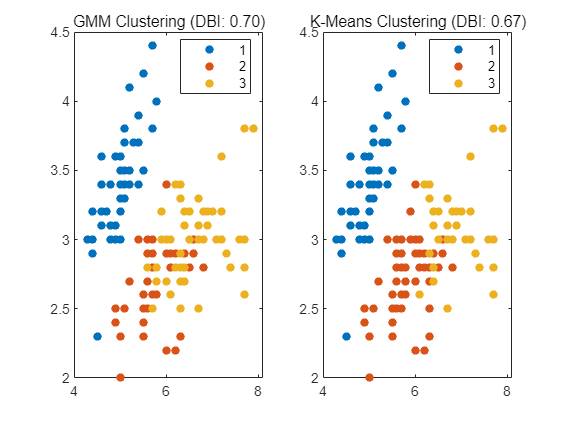

% Load datasets
load fisheriris
iris_data = meas;
iris_labels = species;

% Load Breast Cancer Wisconsin (Diagnostic) dataset
% Load Breast Cancer Wisconsin (Diagnostic) dataset
bc_data_table = readtable('breast_cancer.csv');

% Separate data and labels
bc_labels = bc_data_table{:,2};
bc_data = bc_data_table{:,3:end};

% Separate data and labels
bc_labels = bc_data_table{:,2};
bc_data = bc_data_table{:,3:end};



% Evaluate and plot for Iris, Wisconsin Breast Cancer, and Wine datasets
[iris_dbi_gmm, iris_dbi_kmeans] = cluster_dbi_score(iris_data, iris_labels, 3);

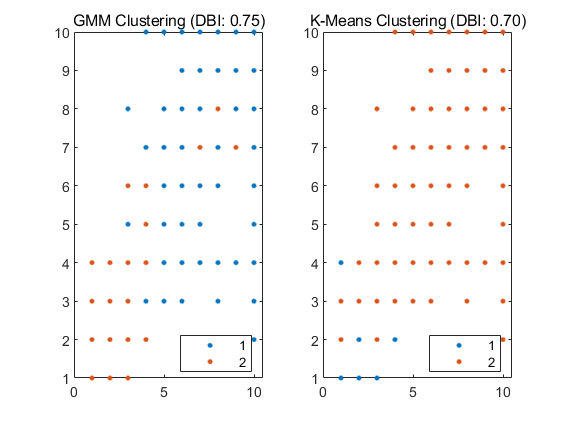

[bc_dbi_gmm, bc_dbi_kmeans] = cluster_dbi_score(bc_data, bc_labels, 2);

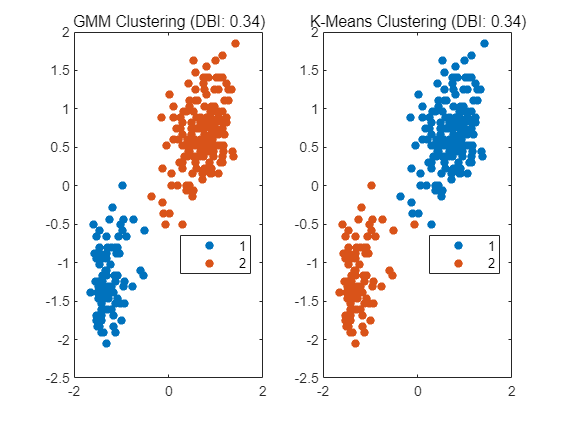

% Load the Old Faithful dataset
faithful_data_table = readtable('faithful.csv');
faithful_data = table2array(faithful_data_table(:, 2:end));

% Standardize the data
faithful_data = zscore(faithful_data);

% Apply GMM and K-Means clustering, calculate DBI scores, and create plots
[faithful_dbi_gmm, faithful_dbi_kmeans] = cluster_dbi_score(faithful_data, [], 2);

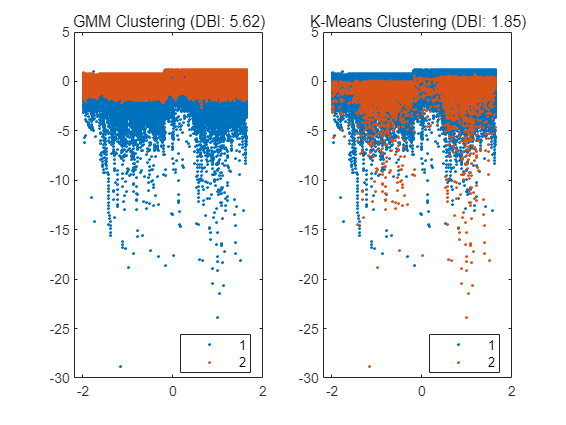

% Load the Credit Card Fraud Detection dataset
creditcard_data_table = readtable('creditcard.csv');
creditcard_data = table2array(creditcard_data_table(:, 1:end-1));
creditcard_labels = table2array(creditcard_data_table(:, end));

% Standardize the data
creditcard_data = zscore(creditcard_data);

% Apply GMM and K-Means clustering, calculate DBI scores, and create plots
[creditcard_dbi_gmm, creditcard_dbi_kmeans] = cluster_dbi_score(creditcard_data, creditcard_labels, 2);

function [dbi_gmm, dbi_kmeans] = cluster_dbi_score(data, labels, num_clusters)
    % Fit GMM
    options = statset('MaxIter', 50000, 'TolFun', 1e-10);
    %options = statset('MaxIter', 3000, 'TolFun', 1e-8);
    %gmm = fitgmdist(data3, n_clusters, 'CovarianceType','diagonal','Options', options);
    gmm_model = fitgmdist(data, num_clusters,'CovarianceType','diagonal','RegularizationValue', 1e-3, 'Options', options);
    
    gmm_clusters = cluster(gmm_model, data);
    
    % Fit K-Means
    [kmeans_clusters, ~] = kmeans(data, num_clusters);
    
    % Calculate DBI scores
    dbi_gmm_obj = evalclusters(data, gmm_clusters, 'DaviesBouldin');
    dbi_kmeans_obj = evalclusters(data, kmeans_clusters, 'DaviesBouldin');
    dbi_gmm = dbi_gmm_obj.CriterionValues;
    dbi_kmeans = dbi_kmeans_obj.CriterionValues;
    
    % Create plots
    figure;
    subplot(1, 2, 1);
    gscatter(data(:, 1), data(:, 2), gmm_clusters);
    title(sprintf('GMM Clustering (DBI: %.2f)', dbi_gmm));
    
    subplot(1, 2, 2);
    gscatter(data(:, 1), data(:, 2), kmeans_clusters);
    title(sprintf('K-Means Clustering (DBI: %.2f)', dbi_kmeans));
end